# **ECE 1473 OFDM Tutorial: **

# **Modulate Message Using OFDM with Cyclic Prefixing**

## **Author: Adam Nichols**

clear, clc

## Introduction:

    In this section, multiple symbols of OFDM will be combined together in the same transmission to send an entire message. In the previous section, single symbols of OFDM were generated. Now, to send a user's message with any reasonable length, multiple symbols must be encoded to form a physical layer packet. Some challenges arise when combining symbols using a rectangular window, which can be resolved using cyclic prefixing.

## Background:

## Message Generation:

    First, a message of random bits will be generated to simulate a user transmitting a signal over the channel. For simplicity, this simulation will assume that the user message fills all OFDM symbols in the message. The user's message will be parallelized into a number of bitstreams equivalent to the number of carriers. See the diagram below to see how the user serial bitstream is parallelized into OFDM symbols and parallel bitstreams.

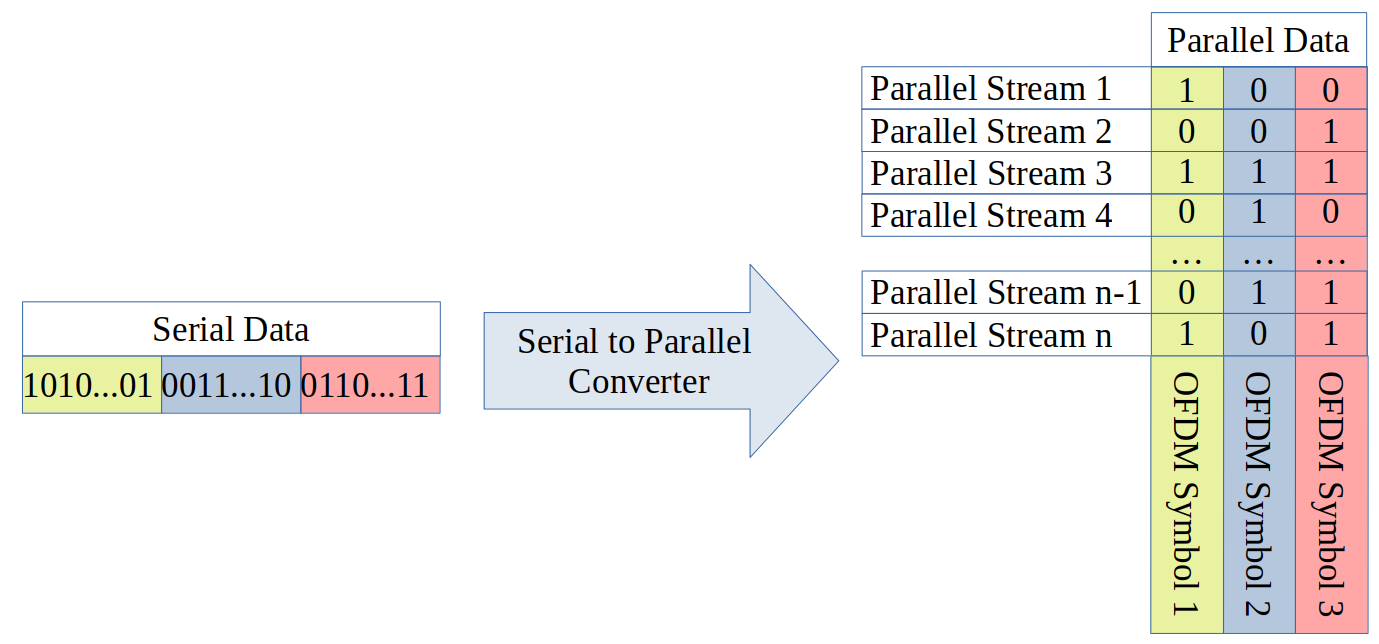

    Pick the number of carriers (number of parallel bitstreams) for the OFDM symbol from the dropdown menu below. Then, pick the number of bits (in multiples of the number of carriers), and the number will be displayed below the dropdown. The bits being sent on the channel will be displayed as a row vector below. After this, the reshape function parallelizes the bits into OFDM symbols.

num_carriers = 32;
num_symbols = 3

num_symbols = 3

num_bits = num_carriers * num_symbols;
bits = RandomBits(num_bits);
transpose(bits)

ans =      1     1     0     1     1     0     0     1     1     1     0     1     1     0     1     0     0     1     1     1     1     0     1     1     1     1     1     0     1     0     1     0     0     0     0     1     1     0     1     0     0     0     1     1     0     0     0     1     1     1


data = reshape(bits,num_carriers,[])

data =      1     0     1
     1     0     1
     0     0     1
     1     1     0
     1     1     0
     0     0     0
     0     1     1
     1     0     0
     1     0     1
     1     0     0


## OFDM Modulation:

    Next, the user bits are modulated into OFDM symbols in the same way as the previous section. The user bits are converted into antipodal values and the IFFT is perfomed to create the baseband signal. 

    Now, all the symbols will be concatenated with a rectangular window. This is a very simple method to 

fourier_coeffs = data*2 - 1;
s_mod = zeros(num_carriers,num_symbols);
for i = 0:num_symbols-1
    s_mod(i*num_carriers+1:(i+1)*num_carriers) = ifft(fourier_coeffs(i*num_carriers+1:(i+1)*num_carriers));
end

    Now, the timing and frequency domain parameters of the OFDM signal are defined. First, the bandwidth of the OFDM message 

bandwidth = 10000;

    Next, the sample rate and the sample times are defined. Recall that the sample rate for modulating OFDM is the bandwidth. Also, as an FYI the symbol time and symbol rate are calculated below. These values represent how long a single symbol of OFDM takes to transmit and how many symbols of OFDM are sent per second.

fs = bandwidth;
ts = 1/fs;
t = transpose((0:num_carriers*num_symbols-1)*ts);

symboltime = ts * num_carriers

symboltime = 0.0032

symbolrate = 1/symboltime

symbolrate = 312.5000

    After this, upsampling is performed to get a better representation of the baseband analog signal and out-of-band effects. A default upsampling value of 4 is chosen, but feel free to use the dropdown to change the upsampling ratio. The new sample rate and sample times are calculated for the upsampled signal.

upsamp = 4;
fs_upsamp = upsamp*fs;
ts_upsamp = ts/upsamp;

    Upsampling with sinc interpolation is done in the same method as in the previous section. This outputs a higher sample rate signal and each symbol is periodic.

s_upsamp = zeros(num_carriers*upsamp,num_symbols);
for i = 0:num_symbols-1
    s_curr = s_mod(i*num_carriers+1:(i+1)*num_carriers);
    if num_symbols > 1
        s_curr = transpose(s_curr);
    end
    s_curr_triple = [s_curr; s_curr; s_curr];
    s_curr_triple_upsamp = resample(s_curr_triple,upsamp,1);
    s_curr_upsamp = s_curr_triple_upsamp(upsamp*num_carriers+1:2*upsamp*num_carriers);
    s_upsamp((i*num_carriers*upsamp+1:(i+1)*num_carriers*upsamp)) = s_curr_upsamp;
end

    Next, all the symbols will be concatenated together. Rectangular windowing is used, which means that the symbols will all be right next to each other. When switching to the next symbol, a jump discontinuity will be present, which causes high frequency (out-of-band) emissions. Recall that the shape of the Fourier transform of the rectangular pulse has a sinc shape in the frequency domain. These spurious emissions from the jump discontinuities will not comply with wireless channel requirements from the FCC. We will see this result when doing spectral analysis in a next step.

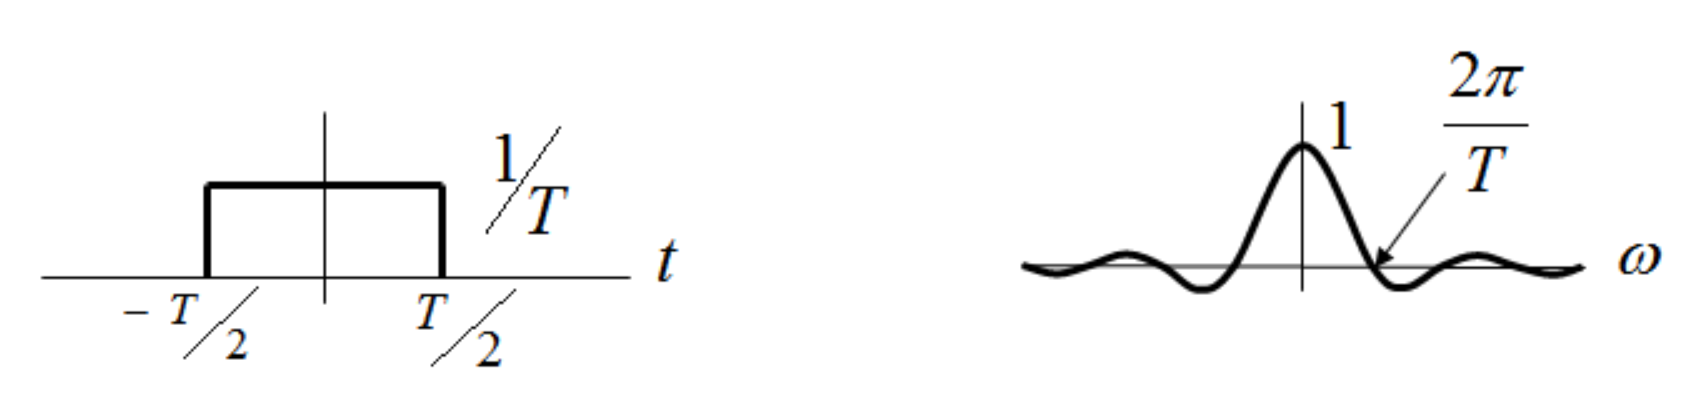

[1] Fourier transform pair of rectangular pulse and sinc function.

s_upsamp_vec = reshape(s_upsamp,[],1);

    Then, the message is zero-padded. This is useful when using filters on the message in a later step. Then, the time vector is generated for the upsampled and zero-padded message. See the figure below for a visual representation of the

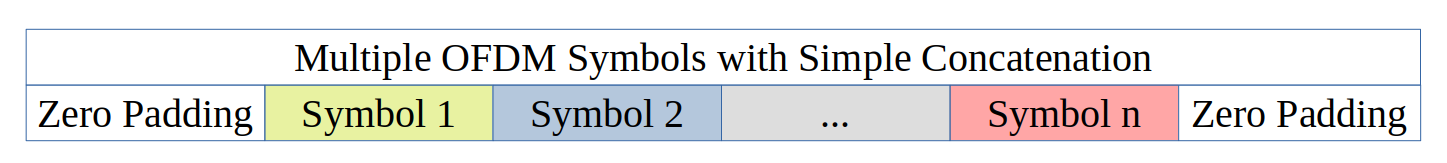

s_upsamp_vec = [zeros(num_carriers*upsamp,1); s_upsamp_vec; zeros(num_carriers*upsamp,1)];
n_upsamp = transpose((1:length(s_upsamp_vec))-num_carriers*upsamp/2-1);
t_upsamp = ts_upsamp * n_upsamp;

    The resulting concatenated signal is plotted in the time domain. Zoom in to view jump discontinuities at the transition times.

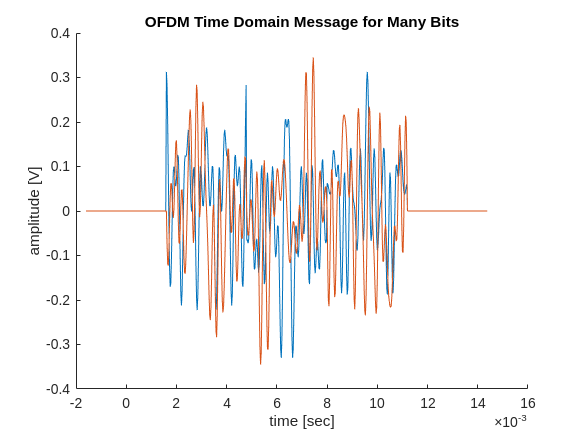

figure
clf
hold on
plot(t_upsamp,real(s_upsamp_vec))
plot(t_upsamp,imag(s_upsamp_vec))
title("OFDM Time Domain Message for Many Bits")
xlabel("time [sec]")
ylabel("amplitude [V]")

    Now, the spectrum of the concatenated message is taken. There are significant high frequency components in this signal which look like the expected response from rectangular windowing. These spectral components would produce out-of-band emissions (spurs) that would make this protocol not conform to wireless channel requirements. 

    One solution to this problem is to much reduce the bandwidth of the message. This means that the spurs would have longer to decay before reaching outside the alloted bandwidth. This is not a great solution because this would greatly reduce the throughput (bit rate) by orders of magnitude. Much of the channel bandwidth would not be used for sending information, but just to let the sidebands decay enough to fit within the channel. A better solution uses filtering to shape the spectrum of the signal to fit in the channel.

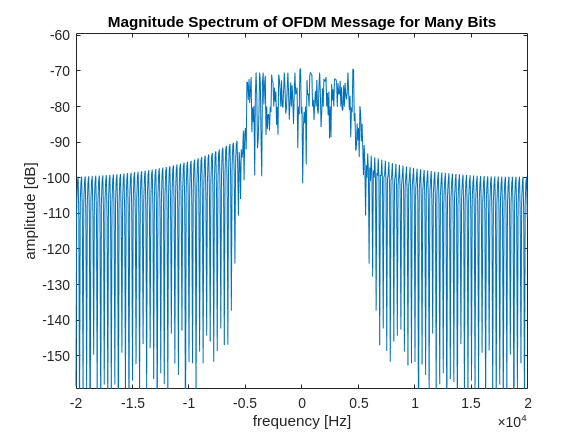

[f_upsamp_all, spec_upsamp_all] = GetSpectrum(s_upsamp_vec,fs_upsamp);
mag_spec_upsamp_all = 20*log10(abs(spec_upsamp_all));

figure
clf
plot(f_upsamp_all,mag_spec_upsamp_all)
title("Magnitude Spectrum of OFDM Message for Many Bits")
xlabel("frequency [Hz]")
ylabel("amplitude [dB]")
ylim([max(mag_spec_upsamp_all)-90, max(mag_spec_upsamp_all)+10])

## Filtering to Meet Channel Specifications:

    To filter the message, a few frequency domain parameters are defined. First, a number of guard carriers will be defined to provide space on the outside of the signal for filtering. This is important because of the behavior of filters at the cutoff frequency. Particularly for analog and IIR filters, there will be phase distortion that will impart group delay on the higher frequency components of the signal. This imparts error in decoding the signal even in ideal, noiseless conditions. By including some extra space in the form of "guard carriers" linear phase is preserved. Additionally, for all frequency based filters (analog, IIR, and FIR) there will be some attenuation at the cutoff frequency. By pushing this frequency out a little further, the high frequency carriers are better preserved. See the figure below for a visual representation of guard carriers (or guard sub-carriers).

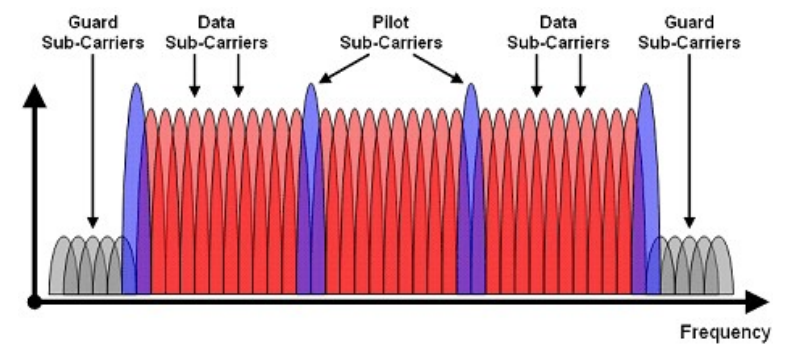

[2] Figure showing a typical frequency domain depiction of OFDM.

    Pick a number of guard carriers below. Try to pick the minimum number that preserves the signal using the frequency domain plot after filtering.

guard_carriers = 8;

    Now, using the guard carriers, the baseband bandwidth of the OFDM message is defined. The data carrying portion of the signal lies within the "useful" bandwidth, which is half of the bandwidth of the passband OFDM signal. The guard bandwidth represents the amount of bandwidth added on each side of the signal to preserve the signal through the filter. Finally, the baseband bandwidth is defined as the sum of the useful and guard bandwidth. This is the bandwidth of the signal passed by the following filter.

bandwidth_useful = bandwidth/2;
bandwidth_guard = guard_carriers/num_carriers*bandwidth/2;
baseband_bandwidth = bandwidth_useful + bandwidth_guard;

    This script uses an FIR filter because of the linear phase and stability properties of FIR filter implementation. This is a digital filter which requires a normalized frequency to the nyquist frequency. 

wc = baseband_bandwidth*2/fs_upsamp;

    The FIR filter is designed below.

filter_length = upsamp*16;
b = fir1(filter_length,wc);
a = zeros(filter_length,1);
a(1) = 1;

    MATLAB's filter function is used to filter the signal. Then, delay imparted by the filter is removed using the autocorrelation function to make the filtered signal and original signal line up in the time domain. This will be used in a following plot.

s_lp = filter(b,a,s_upsamp_vec);

[lp_corr,lp_corr_lags] = xcorr(s_lp,s_upsamp_vec);
delay = lp_corr_lags(lp_corr == max(lp_corr));
s_lp = [s_lp(delay+1:end); zeros(delay,1)];

    The filtered and original signals are plotted below. The original signal is plotted in red and the filtered signal is plotted in blue over the red signal. This shows the error imparted on the signal by filtering. Zoom in to view the differences between the filtered and original versions of the signal. These differences will cause bit errors in detection even in the ideal, noiseless case. This is not the optimal solution. Next, a time domain technique called cyclical prefixing will be introduced to solve these differences between the filtered and original signal.

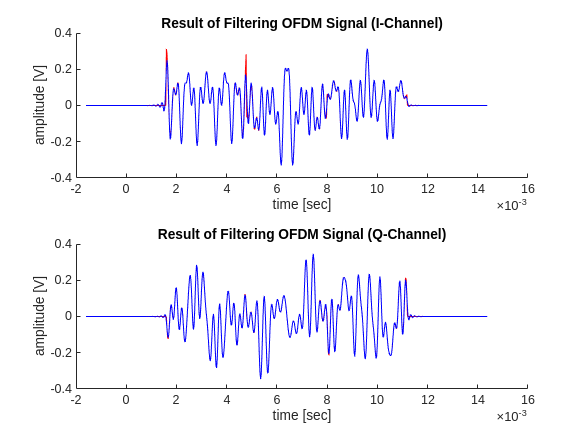

figure
clf
tiledlayout
nexttile
hold on
plot(t_upsamp,real(s_upsamp_vec),'r-')
plot(t_upsamp,real(s_lp),'b-')
xlabel("time [sec]")
ylabel("amplitude [V]")
title("Result of Filtering OFDM Signal (I-Channel)")
nexttile
hold on
plot(t_upsamp,imag(s_upsamp_vec),'r-')
plot(t_upsamp,imag(s_lp),'b-')
xlabel("time [sec]")
ylabel("amplitude [V]")
title("Result of Filtering OFDM Signal (Q-Channel)")

    To quantify this error between the filtered and original signal, the mean-square-error (MSE) is calculated. This metric measures the difference between the signals with a low value showing less difference and a high value show high difference. A low value is preferable. The formula for MSE is as follows:

### 
$$MSE = \frac{1}{n} \sum_{i=1}^{n}{|S_i - \hat{S}_i^{^}|^2$$


[3] Formula for calculating the mean-square-error for a complex time series.

[s_upsamp_symbol_length, ~] = size(s_upsamp);
MSE = 1/(s_upsamp_symbol_length * num_symbols) * sum(abs(s_lp(num_carriers*upsamp+1:end - num_carriers*upsamp)-s_upsamp_vec(num_carriers*upsamp+1:end - num_carriers*upsamp)).^2)

MSE = 1.7222e-04

    Next, the spectrum of the filtered and original signals are compared. Again, the original signal is plotted in red and the filtered signal is plotted in blue over the original signal. The filtered signal is confined to a much reduced bandwidth. This is desireable to meet channel specification, but the errors in the time domain present another challenge. Just as some extra bandwidth was added in the frequency domain to provide room for the filter to transition from passband to stopband, an extra time interval can be added between symbols to let the filter track the symbol more effectively. This is called cyclic prefixing.

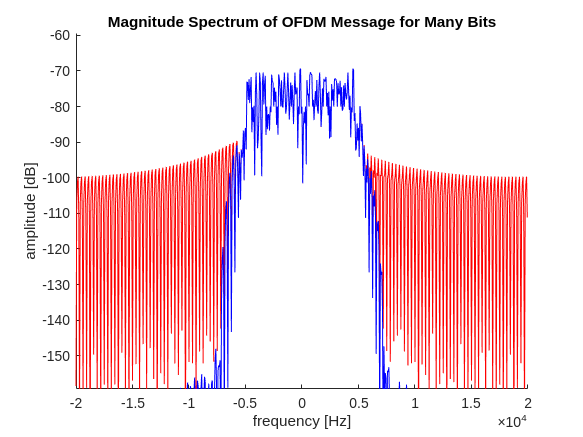

[f_lp, spec_lp] = GetSpectrum(s_lp, fs_upsamp);
mag_spec_lp = 20*log10(abs(spec_lp));

figure
clf
hold on
plot(f_upsamp_all,mag_spec_upsamp_all, 'r-')
plot(f_upsamp_all,mag_spec_lp, 'b-')
title("Magnitude Spectrum of OFDM Message for Many Bits")
xlabel("frequency [Hz]")
ylabel("amplitude [dB]")
ylim([max(mag_spec_upsamp_all)-90, max(mag_spec_upsamp_all)+10])

## Cyclic Prefixing: 

    Cyclic prefixing is a technique widely used in real implementations of OFDM to overcome distortions caused by pulse shaping filters. In essence, cyclic prefixing copies a portion of the end of a symbol to the beginning to allow time for the filter to transit between different OFDM symbols. 

    Why do we copy the end of the symbol to the beginning? Recall that the OFDM symbol is periodic. This means that when the end of the symbol is copied to the beginning, they will line up exactly. This lets the filter have some transition time and nicely flow directly into the important (data containing) part of the transmission. See the figure below for a visual representation of how the end of the OFDM symbol is copied to the beginning. 

    Further, this property can be applied in the opposite direction: copying the beginning of the symbol to the end. In is called cyclic postfixing. In the same way as cyclic prefixing provides a guard interval to transition between symbols, cyclic postfixing provides a guard interval for the end of a symbol. Both cyclic prefixing and postfixing will be used to overcome distortion imparted through filtering.

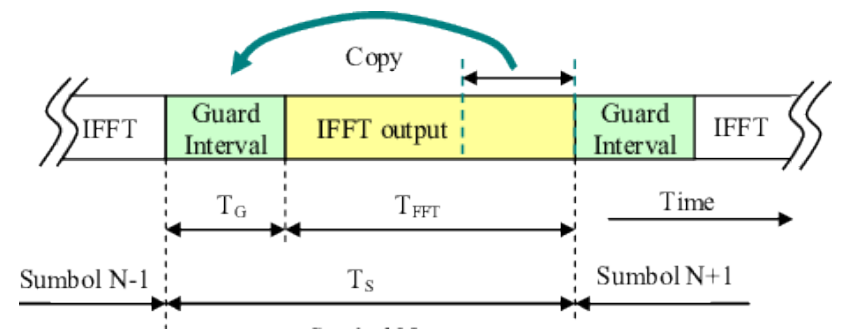

[2] Visual representation of cyclic prefixing.

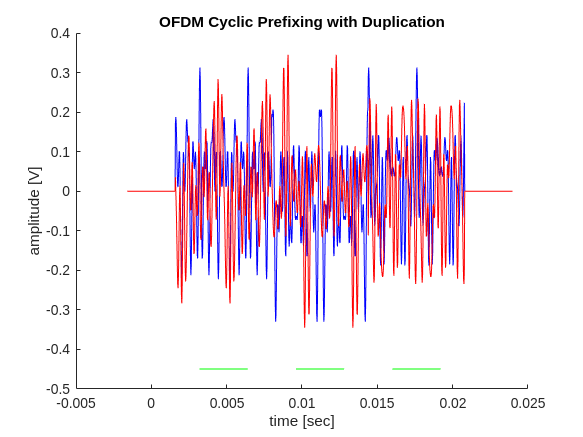



% perform cyclic prefixing/postfixing to reduce spurious emission
% duplicate each symbol for a cyclic prefix, shorten later
s_prefix = [];
for i = 1:num_symbols
    s_prefix = [s_prefix; s_upsamp(s_upsamp_symbol_length/2:end, i); s_upsamp(:, i); s_upsamp(1:s_upsamp_symbol_length/2-1, i)];
end

% zero pad the prefixed/postfixed message
s_prefix = [zeros(num_carriers*upsamp,1); s_prefix; zeros(num_carriers*upsamp,1)];

% generate time vector for prefixed/postfixed signal
n_prefix = transpose((1:length(s_prefix))-num_carriers*upsamp/2-1);
t_prefix = ts_upsamp * n_prefix;

% plot the prefix version of s(t)
figure
clf
hold on
plot(t_prefix,real(s_prefix), 'b-')
plot(t_prefix,imag(s_prefix), 'r-')
for i = 1:num_symbols
    start_bound = num_carriers*upsamp+1 + i*s_upsamp_symbol_length/2 + (i-1)*(s_upsamp_symbol_length + s_upsamp_symbol_length/2);
    end_bound = start_bound + s_upsamp_symbol_length;
    plot([t_prefix(start_bound); t_prefix(end_bound)], [-max(abs(s_prefix))-.1; -max(abs(s_prefix))-.1], 'g-')
end
title("OFDM Cyclic Prefixing with Duplication")
xlabel("time [sec]")
ylabel("amplitude [V]")


% get the spectrum of the prefixed version
[f_prefix, spec_prefix] = GetSpectrum(s_prefix,fs_upsamp);
mag_spec_prefix = 20*log10(abs(spec_prefix));

s_prefix_lp = filter(b,a,s_prefix);


% remove delay from filtered signal to compare for differences
[lp_prefix_corr,lp_prefix_corr_lags] = xcorr(s_prefix_lp,s_prefix);
delay_prefix = lp_prefix_corr_lags(lp_prefix_corr == max(lp_prefix_corr));
s_prefix_lp = [s_prefix_lp(delay_prefix+1:end); zeros(delay_prefix,1)];

% calculate MSE
MSE_prefix = 0;
for i = 1:num_symbols
    start_bound = num_carriers*upsamp+1 + i*s_upsamp_symbol_length/2 + (i-1)*(s_upsamp_symbol_length + s_upsamp_symbol_length/2);
    end_bound = start_bound + s_upsamp_symbol_length;
    MSE_prefix = MSE_prefix + 1/s_upsamp_symbol_length * sum(abs(s_prefix_lp(start_bound:end_bound)-s_prefix(start_bound:end_bound)).^2);
end

MSE_ratio = MSE/MSE_prefix;
fprintf("There is "); fprintf(num2str(MSE_ratio)); fprintf(" times less error through cyclic prefixing.\n")

There is 478.8329 times less error through cyclic prefixing.


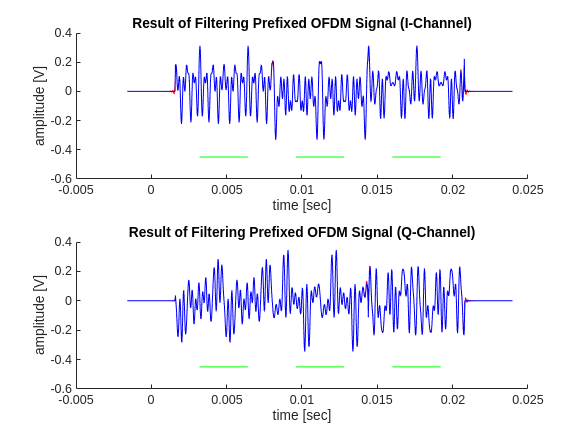

% plot the lowpassed version on same axes as original to show distortion
figure
clf
tiledlayout
nexttile
hold on
plot(t_prefix,real(s_prefix_lp),'r-')
plot(t_prefix,real(s_prefix),'b-')
for i = 1:num_symbols
    start_bound = num_carriers*upsamp+1 + i*s_upsamp_symbol_length/2 + (i-1)*(s_upsamp_symbol_length + s_upsamp_symbol_length/2);
    end_bound = start_bound + s_upsamp_symbol_length;
    plot([t_prefix(start_bound); t_prefix(end_bound)], [-max(abs(s_prefix))-.1; -max(abs(s_prefix))-.1], 'g-')
end
xlabel("time [sec]")
ylabel("amplitude [V]")
title("Result of Filtering Prefixed OFDM Signal (I-Channel)")
nexttile
hold on
plot(t_prefix,imag(s_prefix_lp),'r-')
plot(t_prefix,imag(s_prefix),'b-')
for i = 1:num_symbols
    start_bound = num_carriers*upsamp+1 + i*s_upsamp_symbol_length/2 + (i-1)*(s_upsamp_symbol_length + s_upsamp_symbol_length/2);
    end_bound = start_bound + s_upsamp_symbol_length;
    plot([t_prefix(start_bound); t_prefix(end_bound)], [-max(abs(s_prefix))-.1; -max(abs(s_prefix))-.1], 'g-')
end
xlabel("time [sec]")
ylabel("amplitude [V]")
title("Result of Filtering Prefixed OFDM Signal (Q-Channel)")

## Functions:

% GetSpectrum gets the spectrum of the input signal
% uses the fftshift function to make DC appear at center term
function [f,spectrum] = GetSpectrum(samples, sample_rate)

    % determine the spectrum of the baseband signal
    spectrum = 1/sample_rate*fftshift(fft(samples));
    
    % get bin numbers (centered at 0)
    f_bins = (0:length(samples)-1) - floor(length(samples)/2);

    % define the frequency range
    f = transpose(f_bins * sample_rate / length(f_bins));
end

function bits = RandomBits(num_bits)
    % create a vector of random bits to the required length
    bits = zeros(num_bits,1);
    for i = 1:num_bits
        bits(i) = randi(2,1)-1;
    end
end

## References:

[1] D. Boschen, “How do you visualize the frequency spectrum for a digital waveform?,” *Electrical Engineering Stack Exchange*. https://electronics.stackexchange.com/questions/400275/how-do-you-visualize-the-frequency-spectrum-for-a-digital-waveform

[2] Dr. S. Jacobs, “Unit 8 Lecture 2 - FDM and OFDM,” University of Pittsburgh.

[3] “Mean Square Error - an overview | ScienceDirect Topics,” *www.sciencedirect.com*. https://www.sciencedirect.com/topics/engineering/mean-square-error

‌‌